clc
clf
clear all
close all
rng(0)
plecs

   USAGE: PLECS('CMD','PARAMETER1','PARAMETER2',...)
     Known commands are: get, set, version, hostid, thermal, scope, checkout, nanostep


open('Simulate.slx');

# System parameters

fi = 100e3; % Min. integration frequency
fs = 10e3;  % Sampling frequency
fc = fs;    % Carrier frequency (Natural sampling)

Ti = 1/fi; % Max. simulation step
Ts = 1/fs; % Control step
Tc = 1/fc; % Simulation step

f = 50; % Fundamental output frequency
w = 2*pi*f;

Tf = 7 / f;             % Total simulation time
t_charge = 0;           % Filter capacitor charge
t_load_change1 = 3 / f; % Load change
t_load_change2 = 5 / f; % Load change

Converter

Vdc = 700;
Cul = 2200e-6;

Filter

Rf = 1e-3;
Lf = 2e-3;
Cf = 50e-6;
Vo = 230;

Load

Ro = 180;
Lo = 2e-3;

Measurements

% Current
i_max = 50;             % Saturation
i_std = 0.01 * i_max / 3 % 1% White noise with 3-sigma rule

i_std = 0.1667

% Voltage
v_max = 1000;            % Saturation
v_std = 0.01 * v_max / 3 % 1% White noise with 3-sigma rule

v_std = 3.3333

Reference frame transforms

% abc to alpha-beta
Tabc2ab = (2/3)*[1,      -1/2,       -1/2;
                  0, sqrt(3)/2, -sqrt(3)/2];
% alpha-beta to abc
Tab2abc = (1/2)*[2,        0;
                 -1,  sqrt(3);
                 -1, -sqrt(3)];

# System model

## Equilibrium equations


$$\frac{V_{dc}}{3}\mathbf{u}_s \approx \mathbf{v}_s = (pL_f+R_f) \mathbf{i}_s + \mathbf{v}_o \Rightarrow p\mathbf{i}_s = -\frac{R_f}{L_f} \mathbf{i}_s - \frac{1}{L_f} \mathbf{v}_o + \frac{V_{dc}}{3L_f} \mathbf{u}_s \\
\mathbf{i}_s = pC_f\mathbf{v}_o + \mathbf{i}_o \Rightarrow p \mathbf{v}_o = \frac{1}{C_f} \mathbf{i}_s - \frac{1}{C_f} \mathbf{i}_o$$


## Continuous time


$$\dot{\mathbf{x}} = \mathbf{A}\mathbf{x} + \mathbf{B}\mathbf{u} + \mathbf{E}\mathbf{p}$$



$$\frac{d}{dt}\pmatrix{\mathbf{i}_{s} \cr
                              \mathbf{v}_{o}}
=
\pmatrix{-\frac{R_f}{L_f}\mathbf{I}_2 & -\frac{1}{L_f}\mathbf{I}_2 \cr
               \frac{1}{C_f}\mathbf{I}_2 &   \mathbf{0}_2}
\pmatrix{\mathbf{i}_{s} \cr
                              \mathbf{v}_{o}}
+
\pmatrix{\frac{V_{dc}}{3L_f}\mathbf{1}_{2\times1} \cr
              \mathbf{0}_{2\times1}}
\mathbf{u}_s
+
\pmatrix{\mathbf{0}_{2\times1} \cr
              \frac{-1}{C_f}\mathbf{1}_{2\times1}}
\mathbf{i}_o$$


Model matrices

I2 = eye(2);
O2 = zeros(2);

A = [-Rf/Lf*I2, -1/Lf*I2;
       1/Cf*I2,       O2];
B = [Vdc/(3*Lf)*I2;
                O2];
E = [      O2;
     -1/Cf*I2];

## Discrete time

For control

### One step


$$\mathbf{x}[k+1] = \mathbf{A}_d\mathbf{x}[k] + \mathbf{B}_d\mathbf{u}[k] + \mathbf{E}_d\mathbf{p}[k]$$


nx = size(A, 2) % # of state variables

nx = 4

nu = size(B, 2) % # of control actions

nu = 2

np = size(E, 2) % # of disturbances

np = 2


Ad = expm(Ts*A);
integrated = A\(Ad-eye(nx));
Bd = integrated * B;
Ed = integrated * E;

### Np steps

For control

Np = 5;


$$\mathbf{X}_{1:N_p} = \mathbf{AA}\cdot \mathbf{x}_{0} + \mathbf{BB} \cdot \mathbf{U}_{0:N_p-1} + \mathbf{EE} \cdot \mathbf{P}_{0:N_p-1}$$


With


$$\mathbf{AA}
=
\pmatrix{\mathbf{A}_d \cr
              \mathbf{A}_d^2 \cr
              \vdots \cr
              \mathbf{A}_d^{N_p}}$$


AA = arrayfun(@(t) Ad^t, 1:Np, 'UniformOutput', false);
AA = vertcat(AA{:});


$$\mathbf{BB}
=
\pmatrix{\mathbf{B}_d                                    & \mathbf{0}                                        & \ldots  & \mathbf{0}     \cr
              \mathbf{A}_d\mathbf{B}_d               & \mathbf{B}_d                                    & \ldots  & \mathbf{0}     \cr
              \vdots                                               & \vdots                                               & \ddots & \vdots            \cr
              \mathbf{A}_d^{N_p-1}\mathbf{B}_d & \mathbf{A}_d^{N_p-2}\mathbf{B}_d & \ldots  & \mathbf{B}_d} \\

\mathbf{EE}
=
\pmatrix{\mathbf{E}_d                                    & \mathbf{0}                                        & \ldots  & \mathbf{0}     \cr
              \mathbf{A}_d\mathbf{B}_d               & \mathbf{E}_d                                    & \ldots  & \mathbf{0}     \cr
              \vdots                                               & \vdots                                               & \ddots & \vdots            \cr
              \mathbf{A}_d^{N_p-1}\mathbf{E}_d & \mathbf{A}_d^{N_p-2}\mathbf{E}_d & \ldots  & \mathbf{E}_d} \\

\mathbf{BB} = \mathbf{AAA}\cdot\mathbf{I}_B \\
\mathbf{EE} = \mathbf{AAA}\cdot\mathbf{I}_E \\


\mathbf{AAA}
=
\pmatrix{\mathbf{I}_{n_{x}}        & \mathbf{0}                   & \ldots  & \mathbf{0} \cr
              \mathbf{A}_d               & \mathbf{I}_{n_{x}}        & \ldots  & \mathbf{0} \cr
              \vdots                          & \vdots                          & \ddots & \vdots       \cr
              \mathbf{A}_d^{N_p-1} & \mathbf{A}_d^{N_p-2} & \ldots  & \mathbf{I}_{n_{x}}} \\

\mathbf{I}_B
=
\pmatrix{\mathbf{B}_d & \mathbf{0}    & \ldots  & \mathbf{0}     \cr
              \mathbf{0}     & \mathbf{B}_d & \ldots  & \mathbf{0}     \cr
              \vdots            & \vdots           & \ddots & \vdots            \cr
              \mathbf{0}     & \mathbf{0}    & \ldots  & \mathbf{B}_d} \\

\mathbf{I}_E
=
\pmatrix{\mathbf{E}_d & \mathbf{0}    & \ldots  & \mathbf{0}     \cr
              \mathbf{0}     & \mathbf{E}_d & \ldots  & \mathbf{0}     \cr
              \vdots            & \vdots           & \ddots & \vdots            \cr
              \mathbf{0}     & \mathbf{0}    & \ldots  & \mathbf{E}_d}$$


### AAA

AA_aux = [eye(nx); AA(1:end-nx, :)];
AAA = cell2mat(arrayfun(@(t) [zeros(nx*t, nx); AA_aux(1:end-nx*t, :)], 0:Np-1, 'UniformOutput', false));

### IB

IB = repmat({Bd}, 1, Np);
IB = blkdiag(IB{:});

### BB

BB = AAA * IB;

### IE

IE = repmat({Ed}, 1, Np);
IE = blkdiag(IE{:});

### EE

EE = AAA * IE;

# Kalman Filter

For current load estimation

H_vec = [1, -5 , 7, -11, 13]; % Estimated harmonics
nh = length(H_vec)            % # of estimated harmonics

nh = 5

nH = 2 * nh                   % # of KF state variables (alpha-beta for each harmonic)

nH = 10

J     = [0, -1;  % 90° rotation matrix
         1,  0];

State matrix

A_KF = arrayfun(@(h) h*J, H_vec, 'UniformOutput', false);
A_KF = blkdiag(A_KF{:});
Ad_KF = expm(Ts * A_KF);

Output matrix

C_KF = [1, 0;
        0, 1];
C_KF = repmat(C_KF, 1, nh)

C_KF =      1     0     1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1     0     1


Kalman gain

r = i_std^2;
R_KF = r * I2;
q = r*10;
Q_KF = q * eye(nH);
[P_KF, KF, L_KF, info] = idare(Ad_KF.', C_KF.', Q_KF, R_KF);
KF = KF.'

KF =     0.4383   -0.0000
    0.0000    0.4383
    0.3286   -0.2901
    0.2901    0.3286
    0.3286    0.2900
   -0.2900    0.3286
   -0.0567   -0.4346
    0.4346   -0.0567
   -0.0566    0.4346
   -0.4346   -0.0566


# Control

Grid-forming capacitor voltage control

lambda_i = 0.0001;
lambda_u = 0.00001;
% lambda_i = 1e-10;
% lambda_u = 1e-10;

## Cost function


$$J = \frac{1}{2} \mathbf{u}^T \mathbf{H} \mathbf{u} + \mathbf{f}^T \mathbf{u}$$


### Reference tracking

For ${\mathit{\mathbf{i}}}_s$ and ${\mathit{\mathbf{v}}}_o$

Weights

Wx = eye(nx);
Wx(1, 1) = lambda_i / i_max^2;
Wx(2, 2) = lambda_i / i_max^2;
Wx(3, 3) = 1 / v_max^2;
Wx(4, 4) = 1 / v_max^2;

Wx = repmat({Wx}, 1, Np);
Wx = blkdiag(Wx{:});

Cost function


$$J_x = (\mathbf{X}^* - \mathbf{X})^T \mathbf{W}_x (\mathbf{X}^* - \mathbf{X}) = \mathbf{X}^{*T} \mathbf{W}_x \mathbf{X}^* - \mathbf{X}^{*T} \mathbf{W}_x \mathbf{X} - \mathbf{X}^T \mathbf{W}_x \mathbf{X}^* + \mathbf{X}^T \mathbf{W}_x \mathbf{X} \\

J_x' = - \mathbf{X}^{*T} \mathbf{W}_x \mathbf{X} - \mathbf{X}^T \mathbf{W}_x \mathbf{X}^* + \mathbf{X}^T \mathbf{W}_x \mathbf{X} = -2 \mathbf{X}^{*T} \mathbf{W}_x \mathbf{X} + \mathbf{X}^T \mathbf{W}_x \mathbf{X}$$


With


$$\mathbf{X} = \mathbf{A}\cdot \mathbf{x}_{0} + \mathbf{B}\cdot \mathbf{U} + \mathbf{E}\cdot \mathbf{P}$$


Then


$$J_x' = -2 \mathbf{X}^{*T} \mathbf{W}_x (\mathbf{A} \cdot \mathbf{x}_0 + \mathbf{B} \cdot \mathbf{U} + \mathbf{E} \cdot \mathbf{P}) + (\mathbf{A} \cdot \mathbf{x}_0 + \mathbf{B} \cdot \mathbf{U} + \mathbf{E} \cdot \mathbf{P})^T \mathbf{W}_x (\mathbf{A} \cdot \mathbf{x}_0 + \mathbf{B} \cdot \mathbf{U} + \mathbf{E} \cdot \mathbf{P}) \\

J_x'' = -2 \mathbf{X}^{*T} \mathbf{W}_x (\mathbf{B} \cdot \mathbf{U}) + (\mathbf{B} \cdot \mathbf{U})^T \mathbf{W}_x (\mathbf{A} \cdot \mathbf{x}_0 + \mathbf{B} \cdot \mathbf{U} + \mathbf{E} \cdot \mathbf{P}) + (\mathbf{A} \cdot \mathbf{x}_0 + \mathbf{B} \cdot \mathbf{U} + \mathbf{E} \cdot \mathbf{P})^T \mathbf{W}_x (\mathbf{B} \cdot \mathbf{U}) \\
          = -2 \mathbf{X}^{*T} \mathbf{W}_x (\mathbf{B} \cdot \mathbf{U}) + 2 (\mathbf{A} \cdot \mathbf{x}_0 + \mathbf{B} \cdot \mathbf{U} + \mathbf{E} \cdot \mathbf{P})^T \mathbf{W}_x (\mathbf{B} \cdot \mathbf{U}) \\

J_x''' = (-\mathbf{X}^*+\mathbf{A} \cdot \mathbf{x}_0 + \mathbf{E} \cdot \mathbf{P})^T \mathbf{W}_x \mathbf{B} \cdot \mathbf{U} + \mathbf{U}^T (\mathbf{B}^T \mathbf{W}_x \mathbf{B}) \mathbf{U}$$


Finally,


$$\mathbf{H}_x = 2\mathbf{B}^{T} \mathbf{W}_x \mathbf{B} \\
\mathbf{f}_x   = \mathbf{B}^T \mathbf{W}_x^T (-\mathbf{X}^{*}+\mathbf{A}\cdot \mathbf{x}_0 + \mathbf{E}\cdot \mathbf{P})$$


Hx = 2 * (BB.') * Wx * BB;
% fx = (Wx * BB).' * (-X_ref + AA * x0 + EE * P);

### Control effort

Cost function


$$J_u = (\mathbf{U}^* - \mathbf{U})^T (\mathbf{U}^* - \mathbf{U}) = \mathbf{U}^{*T} \mathbf{U}^* - \mathbf{U}^{*T} \mathbf{U} - \mathbf{U}^T \mathbf{U}^* + \mathbf{U}^T \mathbf{U} \\

J_u' = - \mathbf{U}^{*T} \mathbf{U} - \mathbf{U}^T \mathbf{U}^* + \mathbf{U}^T \mathbf{U} = -2 \mathbf{U}^{*T} \mathbf{U} + \mathbf{U}^T \mathbf{U}$$


Finally,


$$\mathbf{H}_u = 2\mathbf{I}_{n_u\cdot N_p} \\
\mathbf{f}_u   = -2\mathbf{U}^*$$


% Without normalization since the control actions are already normalized
Hu = 2 * eye(nu*Np);
% fu = -2 * U_ref;

### Total cost function

H = Hx + lambda_u * Hu;
H = (H + H.') / 2;
% f = fx + lambda_u * fu;

## Steady-state references

Output voltage


$$\mathbf{v}_o^* = V_o e^{j\omega t} \\
p\mathbf{v}_o^* = j\omega V_o e^{j\omega t}$$


Converter current from the LCK

Converter voltage from the LVK

### From the system equations

Converter current


$$\mathbf{i}_s^* = p C_f \mathbf{v}_o^* + \mathbf{i}_o = j\omega C_f V_o e^{j\omega t} + \mathbf{i}_o \\
p\mathbf{i}_s^* = -\omega^2 C_f V_o e^{j\omega t} + p\mathbf{i}_o$$


Converter voltage


$$\frac{V_{dc}}{3}\mathbf{u}_s = (pL_f+R_f)\mathbf{i}_s^* + \mathbf{v}_o^* \\

\mathbf{u}_s^* = \frac{3}{V_{dc}} \bigr[ L_f p\mathbf{i}_s^* + R_f \mathbf{i}_s^* + \mathbf{v}_o^* \bigl] \\

\mathbf{u}_s^* = \frac{3}{V_{dc}} \bigr[ L_f (-\omega^2 C_f V_o e^{j\omega t} + p\mathbf{i}_o) + R_f (j\omega C_f V_o e^{j\omega t} + \mathbf{i}_o) + V_o e^{j\omega t} \bigl] \\

\mathbf{u}_s^* = \frac{3}{V_{dc}} \bigr[ L_f (-\omega^2 C_f V_o e^{j\omega t}) + L_f p\mathbf{i}_o + R_f (j\omega C_f V_o e^{j\omega t}) + R_f \mathbf{i}_o + V_o e^{j\omega t} \bigl] \\

\mathbf{u}_s^* = \frac{3}{V_{dc}} \bigr[ L_f (-\omega^2 C_f V_o e^{j\omega t}) + R_f (j\omega C_f V_o e^{j\omega t}) + V_o e^{j\omega t} \bigl] + \frac{3}{V_{dc}} \bigr[ L_f p\mathbf{i}_o + R_f \mathbf{i}_o \bigl] \\

\mathbf{u}_s^* = \frac{3}{V_{dc}} \bigr[ (1 - \omega^2 L_f C_f) + j (\omega R_f C_f) \bigl] V_o e^{j\omega t} + \frac{3}{V_{dc}} \bigr[ L_f p\mathbf{i}_o + R_f \mathbf{i}_o \bigl]$$


In vectorial form


$$\mathbf{v}_o^* = V_o
\pmatrix{cos(\omega t) \cr
              sin(\omega t)} \\

\mathbf{i}_s^* = \omega C_f V_o
\pmatrix{-sin(\omega t) \cr
               cos(\omega t)}
+ \mathbf{i}_o \\

\mathbf{u}_s^* = \frac{3V_o}{V_{dc}} \bigr[ (1 - \omega^2 L_f C_f)
\pmatrix{cos(\omega t) \cr
              sin(\omega t)}
+ (\omega R_f C_f)
\pmatrix{-sin(\omega t) \cr
               cos(\omega t)} \bigl]
+ \frac{3}{V_{dc}} \bigr[ L_f p\mathbf{i}_o + R_f \mathbf{i}_o \bigl] $$


## Control action constraints

Control actions

Active phasor hexagon


$$y_{1} = -\sqrt{3}(x-1) \\
y_{2} = \frac{\sqrt{3}}{2} \\
y_{3} = \sqrt{3}(x+1) \\
y_{4} = -\sqrt{3}(x+1) \\
y_{5} = -\frac{\sqrt{3}}{2} \\
y_{6} = \sqrt{3}(x-1) \\$$



$$\mathbf{A}_{lim}\mathbf{u} \leq \mathbf{b}_{lim} \\

\pmatrix{\sqrt{3}  &  1 \cr
              0           &  1 \cr
             -\sqrt{3}  &  1 \cr
             -\sqrt{3}  & -1 \cr
              0            & -1 \cr
              \sqrt{3}  & -1 \cr}
\mathbf{u}
\leq
\pmatrix{\sqrt{3} \cr
              \sqrt{3}/2 \cr
              \sqrt{3} \cr
              \sqrt{3} \cr
              \sqrt{3}/2 \cr
              \sqrt{3} \cr}$$


Aineq = [sqrt(3)   1
         0         1
        -sqrt(3)   1
        -sqrt(3)  -1
         0        -1
         sqrt(3)  -1];

bineq = sqrt(3) * [1
                   1/2
                   1
                   1
                   1/2
                   1];

AAineq = repmat({Aineq}, 1, Np);
AAineq = blkdiag(AAineq{:});

bbineq = repmat({bineq}, 1, Np);
bbineq = vertcat(bbineq{:});

# Predictions

Assuming steady state for every prediction

Also, every vector of predictions has the actual variable value as first element

rot = @(g) [cos(g), -sin(g);
            sin(g),  cos(g)]; % Counter-clockwise rotation matrix

## Disturbance (load current)


$$\mathbf{x}_{KF}
=
\pmatrix{i_{o1p\alpha} & i_{o1p\beta} & i_{o1n\alpha} & i_{o1n\beta} & i_{o2p\alpha} & i_{o2p\beta} & i_{o2n\alpha} & i_{o2n\beta} & \dots & i_{oHn\beta}}^T = (n_h, 1)$$


Every harmonic $h$ in $\alpha \beta \;$ coordinates is predicted rotating it an angle $\theta_s =\omega \;T_s$, counter clockwise for the positive sequence and clockwise for the negative sequence.


$$\mathbf{x}_{KF}[k+2]
=
\pmatrix{\cos(h_1\theta_s) & -\sin(h_1\theta_s)  & 0 & 0 & 0 & 0 & \dots & 0 & 0 \cr
              \sin(h_1\theta_s)  &  \cos(h_1\theta_s) & 0 & 0 & 0 & 0 & \dots & 0 & 0 \cr
               0 & 0 & \cos(h_2\theta_s) &-\sin(h_2\theta_s)  & 0 & 0 & \dots & 0 & 0 \cr
               0 & 0 &  \sin(h_2\theta_s) & cos(h_2\theta_s)  & 0 & 0 & \dots & 0 & 0 \cr
               0 & 0 & 0 & 0 & \cos(h_3\theta_s) & -\sin(h_3\theta_s)  & \dots & 0 & 0 \cr
               0 & 0 & 0 & 0 & \sin(h_3\theta_s) & \cos(h_3\theta_s)  & \dots & 0 & 0 \cr
               0 & 0 & 0 & 0 & 0 & 0 & \dots & \sin(h_n\theta_s) & \cos(h_n\theta_s)}
\mathbf{x}_{KF}[k+1]$$


pn_rot = @(h, t) [rot(H_vec(h)*w*Ts*t)];
Ht_rot = @(t) arrayfun(@(h) pn_rot(h, t), (1:nh)', 'UniformOutput', false);
HT_ROT = cell(Np, 1);
for t = 1:Np
    Ht = Ht_rot(t-1);
    HT_ROT{t} = blkdiag(Ht{:});
end
HT_ROT = cell2mat(HT_ROT);
x_KF_ROT = HT_ROT;

Then to obtain y_KF


$$\mathbf{y}_{KF}[k+1] = \mathbf{C}\cdot\mathbf{x}_{KF}[k+1] \\
\mathbf{y}_{KF}[k+2] = \mathbf{C}\cdot\mathbf{x}_{KF}[k+2] \\
\mathbf{Y}_{KF}
=
\pmatrix{\mathbf{C} & \mathbf{0} & \dots \cr
              \mathbf{0} & \mathbf{C}}$$


CC_KF = repmat({C_KF}, 1, Np);
CC_KF = blkdiag(CC_KF{:});

KF_ROT = CC_KF * x_KF_ROT;
dKF_ROT = CC_KF * x_KF_ROT * A_KF;

# Modulation

M = 

1: DPWMmin

2: DPWmax

3: SVPWM

4: DPWM0

5: DPWM1

6: DPWM2

7: DPWM3

8: SPWM **TAMALA**

HB: Capacitor voltage balancing band

# Simulation

out = sim('Simulate.slx');
vo = out.vo.data;
io = out.io.data;
vo_ref = out.vo_ref.data;
save('vo_ref', 'vo_ref')
save(strcat(['vo_N', num2str(Np)]), 'vo')
save(strcat(['io_N', num2str(Np)]), 'io')

Ns = Tf/Ts+1;
t_sim = Ts * (1:Ns);
vo_ref = load('vo_ref.mat').vo_ref;
vo_N1 = load('vo_N1.mat').vo;
vo_N5 = load('vo_N5.mat').vo;
io_N1 = load('io_N1.mat').io;
io_N5 = load('io_N5.mat').io;

% % Select time interval
% t_steady = 1/f/Ts;
% t_load1 = t_load_change1/Ts;
% t_load2 = t_load_change2/Ts;
% 
% t_ini = t_steady; % First load
% t_ini = t_load1 + t_steady/2; % Second load
% t_ini = t_load2 + t_steady/2; % Third load
% 
% t_fin = t_ini + t_steady;
% 
% t_sim = t_sim(t_ini:t_fin);
% vo_ref = vo_ref(t_ini:t_fin, :);
% vo_N1 = vo_N1(t_ini:t_fin, :);
% vo_N5 = vo_N5(t_ini:t_fin, :);
% io_N1 = io_N1(t_ini:t_fin, :);
% io_N5 = io_N5(t_ini:t_fin, :);

% e_N1 = vo_ref - vo_N1;
% e_N1 = e_N1.^2/3;
% msre_N1 = sqrt(sum(e_N1(:))/Ns);

e_N5 = vo_ref - vo_N5;
e_N5 = e_N5.^2/3;
msre_N5 = sqrt(sum(e_N5(:))/Ns);

% msre_N1
msre_N5

msre_N5 = 5.4469

% msre_N1/msre_N5

% thd_N1a = 100*compute_THD(t_sim, vo_N1(:, 1), f);
% thd_N1b = 100*compute_THD(t_sim, vo_N1(:, 2), f);
% thd_N1c = 100*compute_THD(t_sim, vo_N1(:, 3), f);
% thd_N1 = (thd_N1a + thd_N1b + thd_N1c)/3;
thd_N5a = 100*compute_THD(t_sim, vo_N5(:, 1), f);
thd_N5b = 100*compute_THD(t_sim, vo_N5(:, 2), f);
thd_N5c = 100*compute_THD(t_sim, vo_N5(:, 3), f);
thd_N5 = (thd_N5a + thd_N5b + thd_N5c)/3;

% thd_N1
thd_N5

thd_N5 = 0.9083

% thd_N1/thd_N5

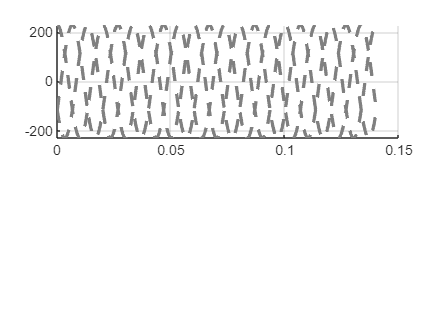

figure;

% ---- Subplot 1: vo_N1 vs vo_ref ----
ax1 = subplot(2,1,1);
hold on; grid on;
plot(t_sim, vo_ref, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 2);

plot(t_sim, vo_N1, '-', 'Color', 'k', 'LineWidth', 0.5);

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

xlim([min(t_sim) max(t_sim)]);
ylabel('$v_{o,abc}$ [V]', 'Interpreter', 'latex');
legend('$v_{o,abc}^*$','','','$v_{o,abc}$, $N=1$', 'Location', 'northeast', 'Interpreter', 'latex');
set(ax1, 'XTickLabel', []);
title('');

% ---- Subplot 2: io_N1 ----
ax2 = subplot(2,1,2);
hold on; grid on;
plot(t_sim, io_N1, '-', 'Color', 'k', 'LineWidth', 0.5);
xlim([min(t_sim) max(t_sim)]);
xlabel('Time [s]');
ylabel('$i_{o,abc}$ [A]', 'Interpreter', 'latex');
legend('$i_{o,abc}$, $N=1$', 'Location', 'northeast', 'Interpreter', 'latex');
title('');

set(gcf, 'Position', 0.4*[100 100 1280 720]); % 16:9 aspect ratio, HD
saveas(gcf, 'results_N1.png');

figure;

% ---- Subplot 1: vo_N5 vs vo_ref ----
ax1 = subplot(2,1,1);
hold on; grid on;
plot(t_sim, vo_ref, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 2);
plot(t_sim, vo_N5, '-', 'Color', 'k', 'LineWidth', 0.5);
xlim([min(t_sim) max(t_sim)]);
ylabel('$v_{o,abc}$ [V]', 'Interpreter', 'latex');
legend('$v_{o,abc}^*$','','','$v_{o,abc}$, $N=5$', 'Location', 'northeast', 'Interpreter', 'latex');
set(ax1, 'XTickLabel', []);
title('');

% ---- Subplot 2: io_N5 ----
ax2 = subplot(2,1,2);
hold on; grid on;
plot(t_sim, io_N5, '-', 'Color', 'k', 'LineWidth', 0.5);
xlim([min(t_sim) max(t_sim)]);
xlabel('Time [s]');
ylabel('$i_{o,abc}$ [A]', 'Interpreter', 'latex');
legend('$i_{o,abc}$, $N=5$', 'Location', 'northeast', 'Interpreter', 'latex');
title('');

set(gcf, 'Position', 0.4*[100 100 1280 720]); % 16:9 aspect ratio, HD
saveas(gcf, 'results_N5.png');